% Problem 5: Logarithmic fit
dosage = [1.00, 2.69, 4.38, 6.07, 7.76, 9.45, 11.14, 12.83, 14.52, 16.21,...
          17.90, 19.59, 21.28, 22.97, 24.66, 26.34, 28.03, 29.72, 31.41,...
          33.10, 34.79, 36.48, 38.17, 39.86, 41.55, 43.24, 44.93, 46.62,...
          48.31, 50.00];
response = [15.10, 25.86, 29.07, 32.70, 35.10, 36.44, 38.85, 40.35, 41.99,...
            42.87, 44.16, 45.13, 46.26, 46.70, 47.68, 48.25, 48.49, 48.92,...
            49.83, 49.60, 50.21, 50.81, 50.79, 51.38, 51.86, 52.15, 52.81,...
            52.72, 53.43, 54.16];

x = log(dosage);
coeffs = polyfit(x, response, 1);
y_fit = polyval(coeffs, x);
Rsq = 1 - sum((response - y_fit).^2) / sum((response - mean(response)).^2);

fprintf('Problem 5 Best fit function: %.2f + %.2f * ln(x)\n', coeffs(2), coeffs(1));

Problem 5 Best fit function: 15.16 + 9.92 * ln(x)


fprintf('R squared value: %.4f\n', Rsq);

R squared value: 0.9975


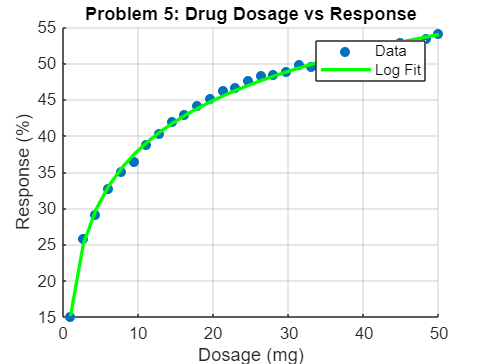


figure;
scatter(dosage, response, 'filled'); hold on;
plot(dosage, y_fit, 'g', 'LineWidth', 2);
title('Problem 5: Drug Dosage vs Response');
xlabel('Dosage (mg)');
ylabel('Response (%)');
legend('Data', 'Log Fit');
grid on;